# Week 02 - Scientific Computing fo Differential Equations

## 2A) Explicit Euler Method with fixed Step-size

t0 = 0;
tN = 10;
N = 1000;
x0 = 1;
lambda = 1;
lambda1 = 0;
lambda2 = -1;
[T,X] = ExplicitEuler(t0,tN,N,x0,lambda);

Unrecognized function or variable 'func'.

Error in ExplicitEuler (line 16)
        f = feval(func,T(:,k),X(:,k),varargin{:});

[T1,X1] = ExplicitEuler(t0,tN,N,x0,lambda1);
[T2,X2] = ExplicitEuler(t0,tN,N,x0,lambda2);

plot(T,X)
title("Explicit Euler Method")
hold on 
plot(T1,X1)
plot(T2,X2)
hold off
xlabel("t")
ylabel("x(t)")
xlim([0 10])
ylim([0 10])
legend('lambda = 1','lambda = 0','lambda = -1')

## 2B) Implicit Euler Method on linear System

t0 = 0;
tN = 10;
N = 1000;
x0 = 1;
lambda = 1;
lambda1 = 0;
lambda2 = -1;
[T,X] = ImplicitEuler(t0,tN,N,x0,lambda);
[T1,X1] = ImplicitEuler(t0,tN,N,x0,lambda1);
[T2,X2] = ImplicitEuler(t0,tN,N,x0,lambda2);

plot(T,X)
title("Implicit Euler Method on linear System")
hold on 
plot(T1,X1)
plot(T2,X2)
hold off
xlabel("t")
ylabel("x(t)")
xlim([0 10])
ylim([0 10])
legend('lambda = 1','lambda = 0','lambda = -1')

## Trapezoidal Method on linear System

t0 = 0;
tN = 10;
N = 1000;
x0 = 1;
lambda = 1;
lambda1 = 0;
lambda2 = -1;
[T,X] = Trapezoidal(t0,tN,N,x0,lambda);
[T1,X1] = Trapezoidal(t0,tN,N,x0,lambda1);
[T2,X2] = Trapezoidal(t0,tN,N,x0,lambda2);

plot(T,X)
title("Trapezoidal Euler Method on linear System")
hold on 
plot(T1,X1)
plot(T2,X2)
hold off
xlabel("t")
ylabel("x(t)")
xlim([0 10])
ylim([0 10])
legend('lambda = 1','lambda = 0','lambda = -1')

## Exponential of Matrix A

A = [2 2 2; 1 1 1 ; 3 3 3]
expm(A)
exponentialMatrix(A)

## 2C) Van der Pol problem with Implicit and Explicit Euler Method

## VanderPolfunjac

x0 = [2.0;0.0];
mu = 10;
t = 50;
[f,J] = VanderPolfunjac(t,x0,mu)

## Solution with Explicit Euler method

t0 = 0;
tN = 50;
N = 10000;
x0 = [2.0;0.0];
mu = 10;
[T,X] = ExplicitEuler(@VanderPolfunjac,t0,tN,N,x0,mu);

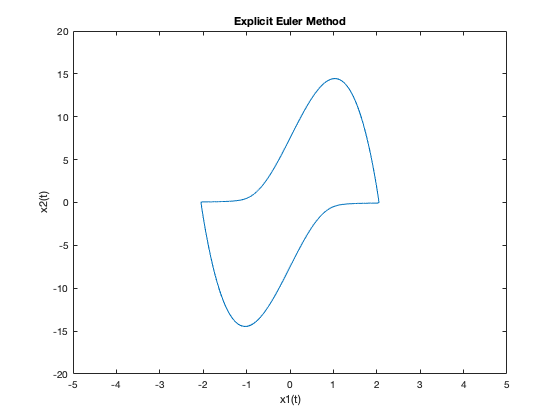

plot(X(:,1),X(:,2))
title("Explicit Euler Method")
xlabel("x1(t)")
ylabel("x2(t)")
hold off
xlim([-5 5])
ylim([-20 20])

## Solution with Implicit Euler Method

t0 = 0;
tN = 50;
N = 10000;
x0 = [2.0;0.0];
mu = 10;
[T,X] = ImplicitEulerFixedSS(@VanderPolfunjac,t0,tN,N,x0,mu);

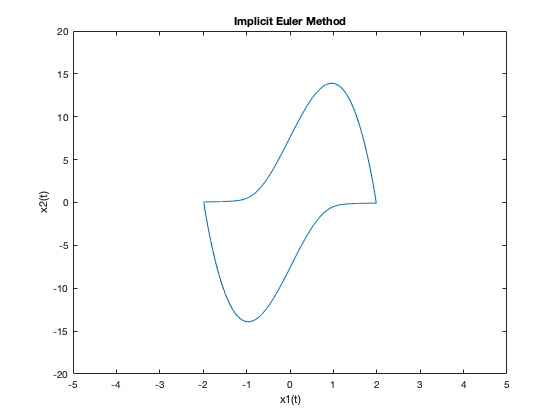

plot(X(:,1),X(:,2))
title("Implicit Euler Method")
xlabel("x1(t)")
ylabel("x2(t)")
hold off
xlim([-5 5])
ylim([-20 20])